# Create and Customize Function Mesh Plots

### Define a 3-D Function

Create a function that defines a surface as $f\left(x,y\right)=\sin \left(x\right)+\cos \left(y\right)$. 

fun = @(x,y) sin(x)+cos(y);

### Basic Function Mesh Plot

Providing the function handle to `fmesh `will evaluate and plot the function over the default $\left\lbrack -5,5\right\rbrack \;$interval for *x *and *y*.

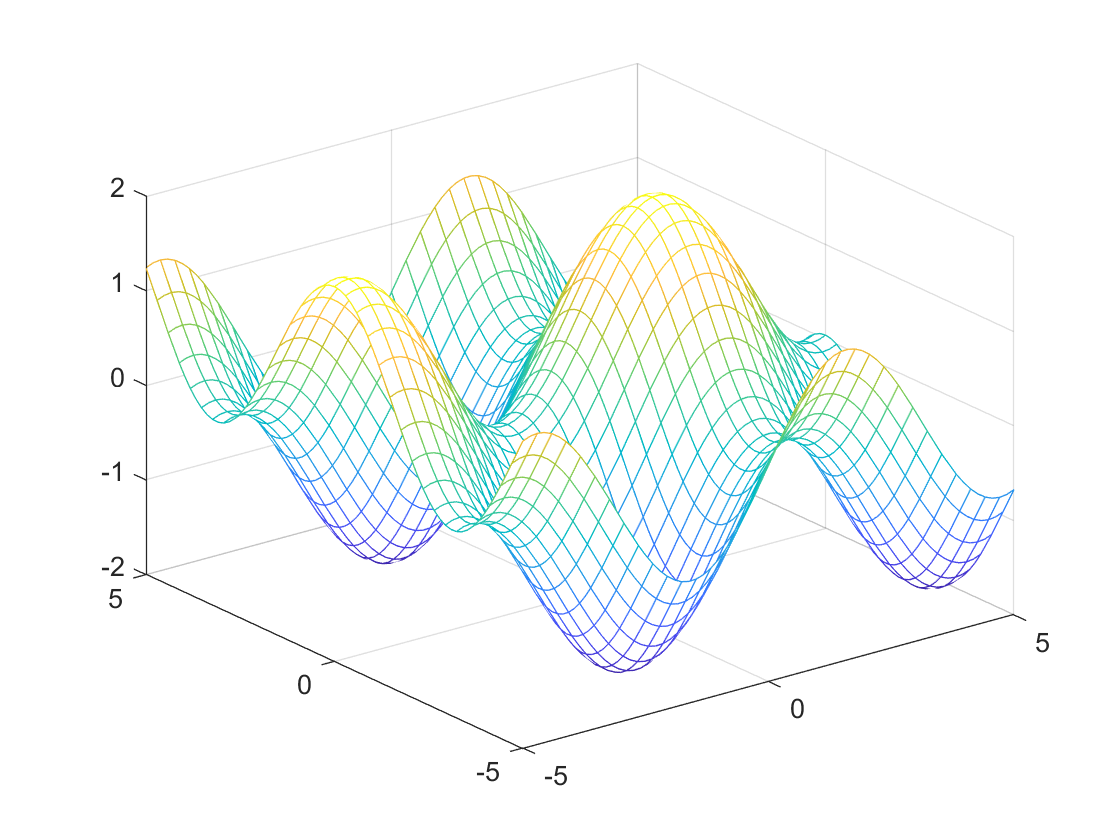

fmesh(fun);

## Customizations

### Specify Surface Properties

The appearance of the surface generated by the mesh lines can be specified to adjust the plot appearance. To reduce the overall presence of the surface lines, the *LineWidth *property can be reduced, and the density of evaluated lines can be reduced by setting the *MeshDensity *property. A overall fixed color can be set instead of the colormap by defining the *EdgeColor *property.

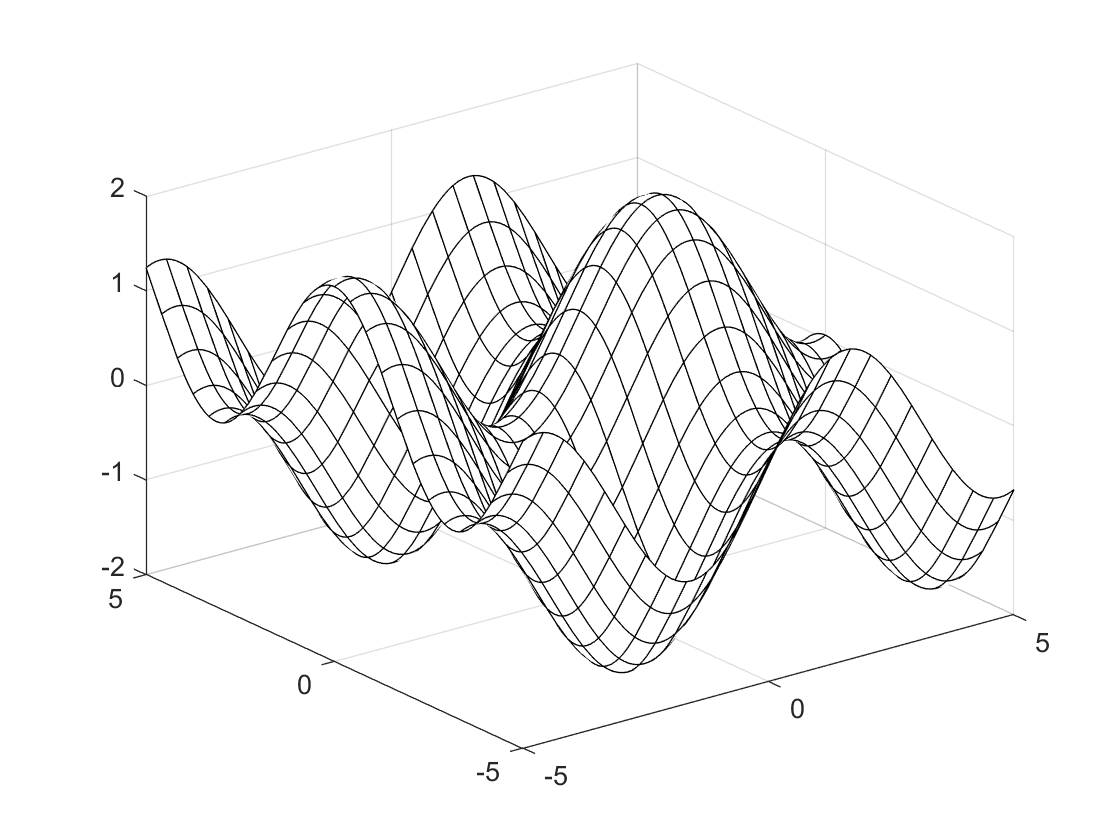

EdgeColor = 'k';
LineWidth = 0.5;
MeshDensity = 25;

fmesh(fun,...
    "EdgeColor", EdgeColor,...                  % Specify the overall plot color
    "LineWidth", LineWidth,...                  % Specify the plot line thicknesses
    "MeshDensity", MeshDensity);                    % Specify the number of lines represented in the plot

### Specify Parametric Functions Over a Domain

`fmesh `will plot a set of parametric functions if three input functions are provided. Create a parametric function defined by the equations: $x=\mathrm{rcos}\left(s\right)\sin \left(t\right),y=\mathrm{rsin}\left(s\right)\sin \left(t\right),\;z=\mathrm{rcos}\left(t\right)\;$where $r=2+\sin \left(7s+5t\right)$. Additionally, with a parametric function it may be necessary to overwrite the default range of values. Define a range for the functions to be evaluated over as the next input. The range specifies the lower and upper limits of each variable as a concatenated row vector.

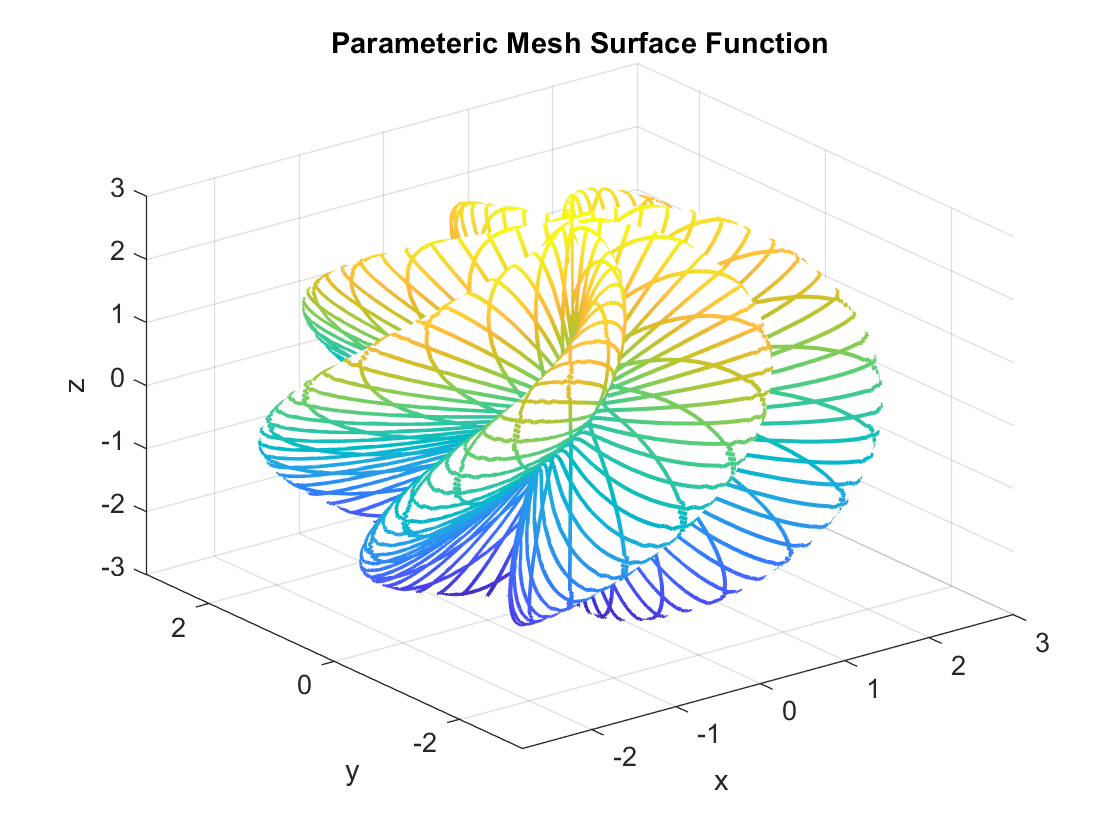

sLims = [0 2*pi];
tLims = [0 pi];
evalRange = horzcat(sLims, tLims);              % Create a vector of evaluation limits

r = @(s,t) 2 + sin(7.*s + 5.*t);
x = @(s,t) r(s,t).*cos(s).*sin(t);
y = @(s,t) r(s,t).*sin(s).*sin(t);
z = @(s,t) r(s,t).*cos(t);

fm = fmesh(x,y,z,...
    evalRange,...                               % Set the evaluation range
    "LineWidth",1.5);                           % Increase the line width                 

title('Parameteric Mesh Surface Function')
xlabel('x')
ylabel('y')
zlabel('z')

## Additional Information

### **Get All Fmesh Properties**

Graphics objects in MATLAB have many properties. To see all the properties of a fmesh plot, uncomment the following code

% get(fm)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[fmesh](https://www.mathworks.com/help/matlab/ref/fmesh.html)